# 信号采样

#### 采样信号的频谱

无限带宽连续长度的信号对应连续的频谱

有限带宽连续长度的信号对应离散的频谱

无限带宽离散长度的信号对应连续周期的频谱

有限带宽离散长度的信号对用离散周期的频谱

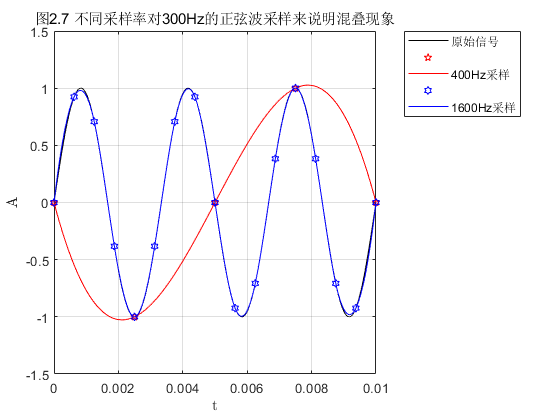

T = 10e-3;
F = 300;
t1 = 0:T/10000:T-T/10000;

A = sin(2*pi*F*t1);

figure
plot(t1,A,'k'),hold on
title('图2.7 不同采样率对300Hz的正弦波采样来说明混叠现象'),xlabel('t','Interpreter','latex'),ylabel('A','Interpreter','latex')
grid on

% 不满足奈奎斯特采样定理
fs1 = 400;  % 设置采样频率
dt1 = 1/fs1;% 定义采样间隔

t1 = 0:dt1:T;

A1 = sin(2*pi*F*t1);

cs1 = spline(t1,A1);
xx1 = linspace(t1(1),t1(end),1000); % 插值点
yy1 = ppval(cs1,xx1); % 插值

plot(t1,A1,'rp'),hold on
plot(xx1,yy1,'r'),hold on

% 满足奈奎斯特采样定理
fs2 = 1600;  % 设置采样频率
dt2 = 1/fs2; % 定义采样间隔

t2 = 0:dt2:T;

A2 = sin(2*pi*F*t2);

cs2 = spline(t2,A2);
xx2 = linspace(t2(1),t2(end),1000); % 插值点
yy2 = ppval(cs2,xx2); % 插值

plot(t2,A2,'bh'),hold on
plot(xx2,yy2,'b'),hold on

set(legend,'Location','NorthEastOutside')
legend('原始信号','','400Hz采样','','1600Hz采样')

#### 实信号采样

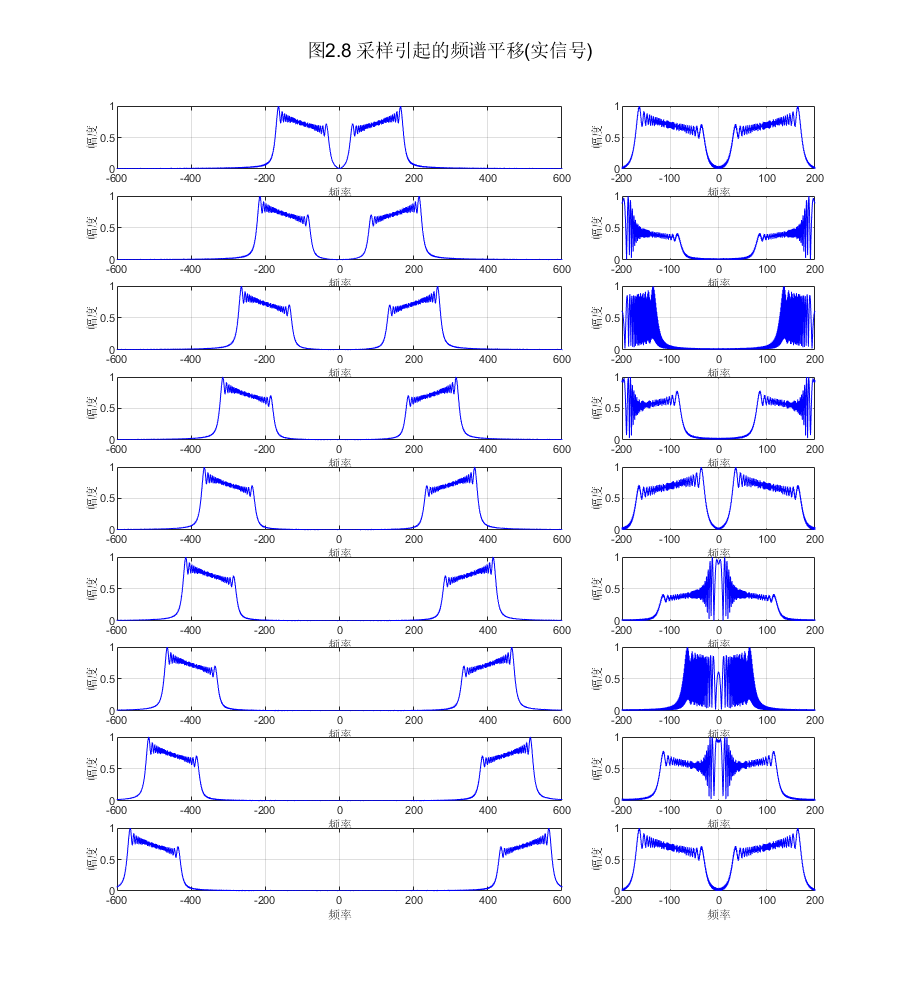

% 参数设置
T = 1;
B = 150;
K = B/T;

set(figure,'position',[100,100,900,1000]);

for i = 1:1:9
    
    f0 = 25+(i-1)*50;

    % 原始信号
    dt = 1/2000;
    t1 = 0:dt:T-dt;
    
    At = t1+2;
    At = At./max(max(At)); % 信号幅度修正
    
    st = cos(2*pi*(f0*t1+0.5*K*t1.^2)).*At;
    
    % 傅里叶变换
    N1 = 2^20;
    df = 1/dt;
    f1 = -df/2:df/N1:df/2-df/N1;
    
    Sf = fft(st,N1);
    Sf = fftshift(abs(Sf)/max(abs(Sf)));
    
    % 采样信号
    Fs = 400;
    Dt = 1/Fs;
    t2 = 0:Dt:T-Dt;
    
    Bt = t2+2;
    Bt = Bt./max(max(Bt));
    
    st_c = cos(2*pi*(f0*t2+0.5*K*t2.^2)).*Bt;
    
    % 傅里叶变换
    N2 = 2^20;
    f2 = -Fs/2:Fs/N2:Fs/2-Fs/N2;
    
    Sf_c = fft(st_c,N2);
    Sf_c = fftshift(abs(Sf_c)/max(abs(Sf_c)));
    
    % figure 
    % plot(t1,st,'b')
    % xlabel('t'),ylabel('st')
    %grid on
    
    % figure
    % plot(f1,Sf,'b')
    % xlabel('f'),ylabel('Sf')
    % grid on
    
    % figure
    % plot(f2,Sf_c,'b')
    % xlabel('f'),ylabel('Sf_c')
    % grid on
    
    subplot(9,3,[3*(i-1)+1,3*(i-1)+2]),plot(f1,Sf,'b')
    xlabel('频率'),ylabel('幅度')
    axis([-600 600, 0 1])
    grid on
    subplot(9,3,3*i)
    plot(f2,Sf_c,'b')
    xlabel('频率'),ylabel('幅度')
    axis([-200 200, 0 1])
    grid on
end

suptitle('图2.8 采样引起的频谱平移(实信号)')

#### 复信号采样

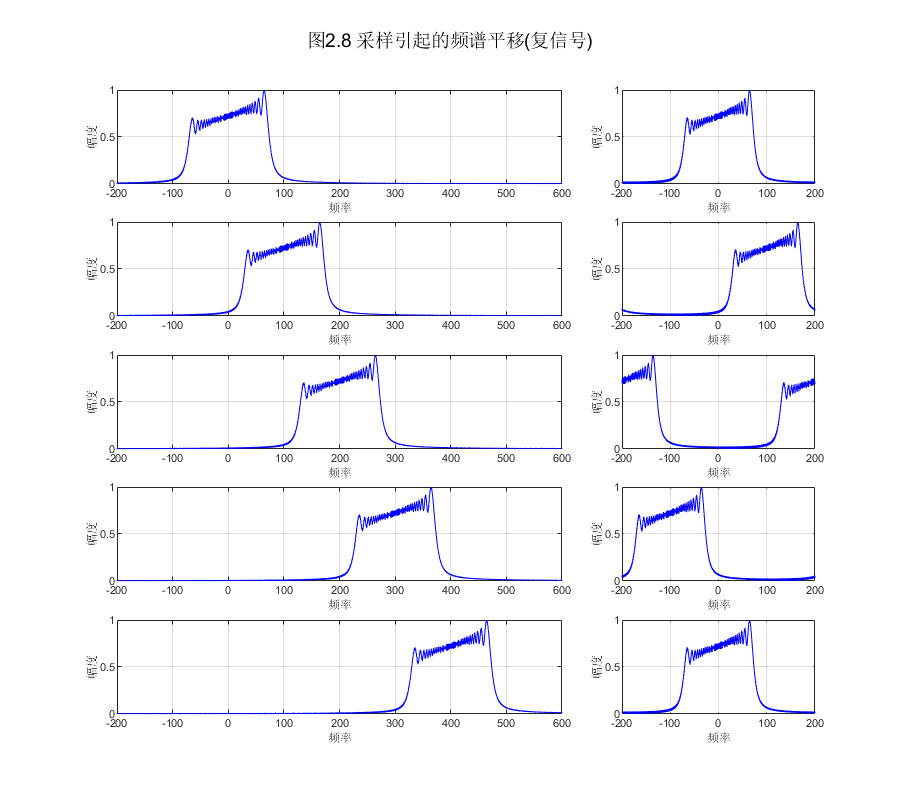

% 参数设置
T = 1;
B = 150;
K = B/T;

set(figure,'position',[100,100,900,800]);

for i = 1:1:5
    
    f0 = -75+(i-1)*100;

    % 原始信号
    dt = 1/2000;
    t1 = 0:dt:T-dt;
    
    At = t1+2;
    At = At./max(max(At)); % 信号幅度修正
    
    st = exp(1i*2*pi*(f0*t1+0.5*K*t1.^2)).*At;
    
    % 傅里叶变换
    N1 = 2^20;
    df = 1/dt;
    f1 = -df/2:df/N1:df/2-df/N1;
    
    Sf = fft(st,N1);
    Sf = fftshift(abs(Sf)/max(abs(Sf)));
    
    % 采样信号
    Fs = 400;
    Dt = 1/Fs;
    t2 = 0:Dt:T-Dt;
    
    Bt = t2+2;
    Bt = Bt./max(max(Bt));
    
    st_c = exp(1i*2*pi*(f0*t2+0.5*K*t2.^2)).*Bt;
    
    % 傅里叶变换
    N2 = 2^20;
    f2 = -Fs/2:Fs/N2:Fs/2-Fs/N2;
    
    Sf_c = fft(st_c,N2);
    Sf_c = fftshift(abs(Sf_c)/max(abs(Sf_c)));
    
    % figure 
    % plot(t1,st,'b')
    % xlabel('t'),ylabel('st')
    %grid on
    
    % figure
    % plot(f1,Sf,'b')
    % xlabel('f'),ylabel('Sf')
    % grid on
    
    % figure
    % plot(f2,Sf_c,'b')
    % xlabel('f'),ylabel('Sf_c')
    % grid on
    
    subplot(5,3,[3*(i-1)+1,3*(i-1)+2]),plot(f1,Sf,'b')
    xlabel('频率'),ylabel('幅度')
    axis([-200 600, 0 1])
    grid on
    subplot(5,3,3*i)
    plot(f2,Sf_c,'b')
    xlabel('频率'),ylabel('幅度')
    axis([-200 200, 0 1])
    grid on
end

suptitle('图2.8 采样引起的频谱平移(复信号)')